clc;
clear;
runtime=80

runtime = 80

for count=1:runtime
Road_length  =100;
car_number   = 20;
acceleration = 2+0.1*count
deceleration =-6.5;
a_d(count)=acceleration/Road_length
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop
for l=1:40
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end

S(count)=std(m);
averagespeed(count) = mean(m);
maxave(count)=max(m)-averagespeed(count)
minave(count)=averagespeed(count)-min(m)
acc(count)=acceleration;
%percentage
end

acceleration = 2.1000

a_d = 0.0210

maxave = 1.2671

minave = 0.9029

acceleration = 2.2000

a_d =     0.0210    0.0220


maxave =     1.2671    2.3345


minave =     0.9029    1.0531


acceleration = 2.3000

a_d =     0.0210    0.0220    0.0230


maxave =     1.2671    2.3345    2.5764


minave =     0.9029    1.0531    0.9339


acceleration = 2.4000

a_d =     0.0210    0.0220    0.0230    0.0240


maxave =     1.2671    2.3345    2.5764    2.4974


minave =     0.9029    1.0531    0.9339    1.0366


acceleration = 2.5000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829


minave =     0.9029    1.0531    0.9339    1.0366    0.6275


acceleration = 2.6000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861


acceleration = 2.7000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659


acceleration = 2.8000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608


acceleration = 2.9000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125


acceleration = 3

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143


acceleration = 3.1000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268


acceleration = 3.2000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479


acceleration = 3.3000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602


acceleration = 3.4000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699


acceleration = 3.5000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206


acceleration = 3.6000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318


acceleration = 3.7000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906


minave =     0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189


acceleration = 3.8000

a_d =     0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380


maxave =     1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064


minave = 1×18
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423


acceleration = 3.9000

a_d = 1×19
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390


maxave = 1×19
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959


minave = 1×19
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991


acceleration = 4

a_d = 1×20
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400


maxave = 1×20
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701


minave = 1×20
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984


acceleration = 4.1000

a_d = 1×21
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410


maxave = 1×21
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603


minave = 1×21
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734


acceleration = 4.2000

a_d = 1×22
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420


maxave = 1×22
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767


minave = 1×22
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004


acceleration = 4.3000

a_d = 1×23
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430


maxave = 1×23
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652


minave = 1×23
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748


acceleration = 4.4000

a_d = 1×24
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440


maxave = 1×24
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516


minave = 1×24
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301


acceleration = 4.5000

a_d = 1×25
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450


maxave = 1×25
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512


minave = 1×25
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518


acceleration = 4.6000

a_d = 1×26
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460


maxave = 1×26
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650


minave = 1×26
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117


acceleration = 4.7000

a_d = 1×27
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470


maxave = 1×27
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106


minave = 1×27
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787


acceleration = 4.8000

a_d = 1×28
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480


maxave = 1×28
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863


minave = 1×28
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777


acceleration = 4.9000

a_d = 1×29
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


maxave = 1×29
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605


minave = 1×29
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554


acceleration = 5

a_d = 1×30
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×30
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×30
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.1000

a_d = 1×31
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×31
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×31
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.2000

a_d = 1×32
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×32
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×32
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.3000

a_d = 1×33
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×33
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×33
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.4000

a_d = 1×34
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×34
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×34
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.5000

a_d = 1×35
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×35
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×35
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.6000

a_d = 1×36
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×36
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×36
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.7000

a_d = 1×37
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×37
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×37
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.8000

a_d = 1×38
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×38
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×38
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 5.9000

a_d = 1×39
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×39
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×39
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6

a_d = 1×40
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×40
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×40
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.1000

a_d = 1×41
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×41
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×41
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.2000

a_d = 1×42
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×42
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×42
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.3000

a_d = 1×43
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×43
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×43
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.4000

a_d = 1×44
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×44
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×44
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.5000

a_d = 1×45
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×45
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×45
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.6000

a_d = 1×46
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×46
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×46
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.7000

a_d = 1×47
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×47
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×47
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.8000

a_d = 1×48
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×48
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×48
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 6.9000

a_d = 1×49
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×49
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×49
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7

a_d = 1×50
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×50
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×50
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.1000

a_d = 1×51
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×51
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×51
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.2000

a_d = 1×52
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×52
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×52
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.3000

a_d = 1×53
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×53
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×53
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.4000

a_d = 1×54
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×54
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×54
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.5000

a_d = 1×55
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×55
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×55
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.6000

a_d = 1×56
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×56
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×56
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.7000

a_d = 1×57
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×57
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×57
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.8000

a_d = 1×58
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×58
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×58
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 7.9000

a_d = 1×59
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×59
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×59
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8

a_d = 1×60
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×60
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×60
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.1000

a_d = 1×61
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×61
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×61
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.2000

a_d = 1×62
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×62
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×62
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.3000

a_d = 1×63
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×63
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×63
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.4000

a_d = 1×64
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×64
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×64
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.5000

a_d = 1×65
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×65
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×65
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.6000

a_d = 1×66
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×66
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×66
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.7000

a_d = 1×67
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×67
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×67
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.8000

a_d = 1×68
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×68
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×68
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 8.9000

a_d = 1×69
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×69
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×69
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9

a_d = 1×70
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×70
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×70
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.1000

a_d = 1×71
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×71
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×71
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.2000

a_d = 1×72
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×72
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×72
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.3000

a_d = 1×73
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×73
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×73
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.4000

a_d = 1×74
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×74
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×74
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.5000

a_d = 1×75
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×75
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×75
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.6000

a_d = 1×76
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×76
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×76
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.7000

a_d = 1×77
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×77
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×77
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.8000

a_d = 1×78
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×78
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×78
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 9.9000

a_d = 1×79
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×79
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×79
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


acceleration = 10

a_d = 1×80
    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


maxave = 1×80
    1.2671    2.3345    2.5764    2.4974    2.7829    2.9387    3.5410    1.4901    2.3111    1.2509    2.1224    1.9644    3.0551    1.4133    1.2057    2.0031    4.5906    1.6064    1.6959    1.3701    1.8603    2.7767    1.5652    6.1516    6.0512    2.7650    2.9106    1.0863    1.0605    1.0978


minave = 1×80
    0.9029    1.0531    0.9339    1.0366    0.6275    1.0861    1.0659    0.7608    0.7125    0.8143    1.1268    1.2479    1.2602    1.2699    1.2206    1.1318    1.3189    1.1423    1.1991    1.2984    1.0734    1.3004    1.0748    1.8301    1.3518    1.5117    1.1787    1.7777    1.7554    1.2570


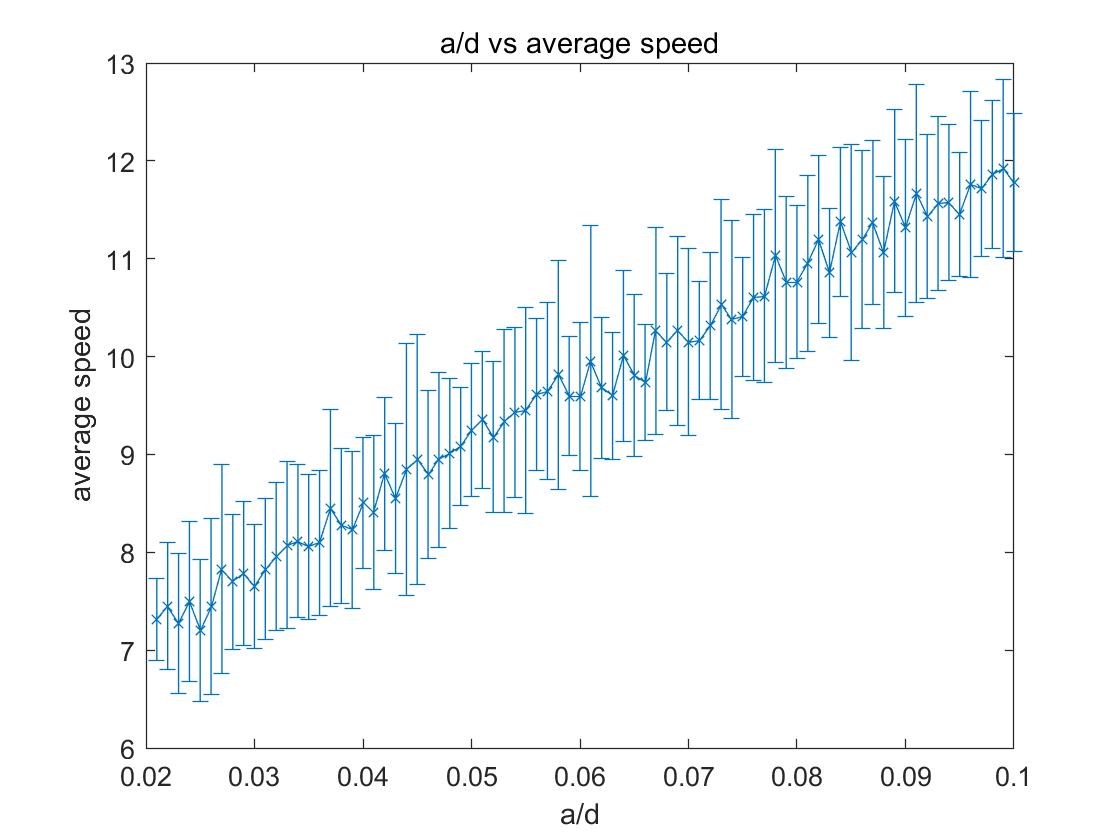

errorbar(a_d,averagespeed,S,"-x","MarkerSize",5)
title("a/d vs average speed") 
xlabel('a/d')
ylabel('average speed')

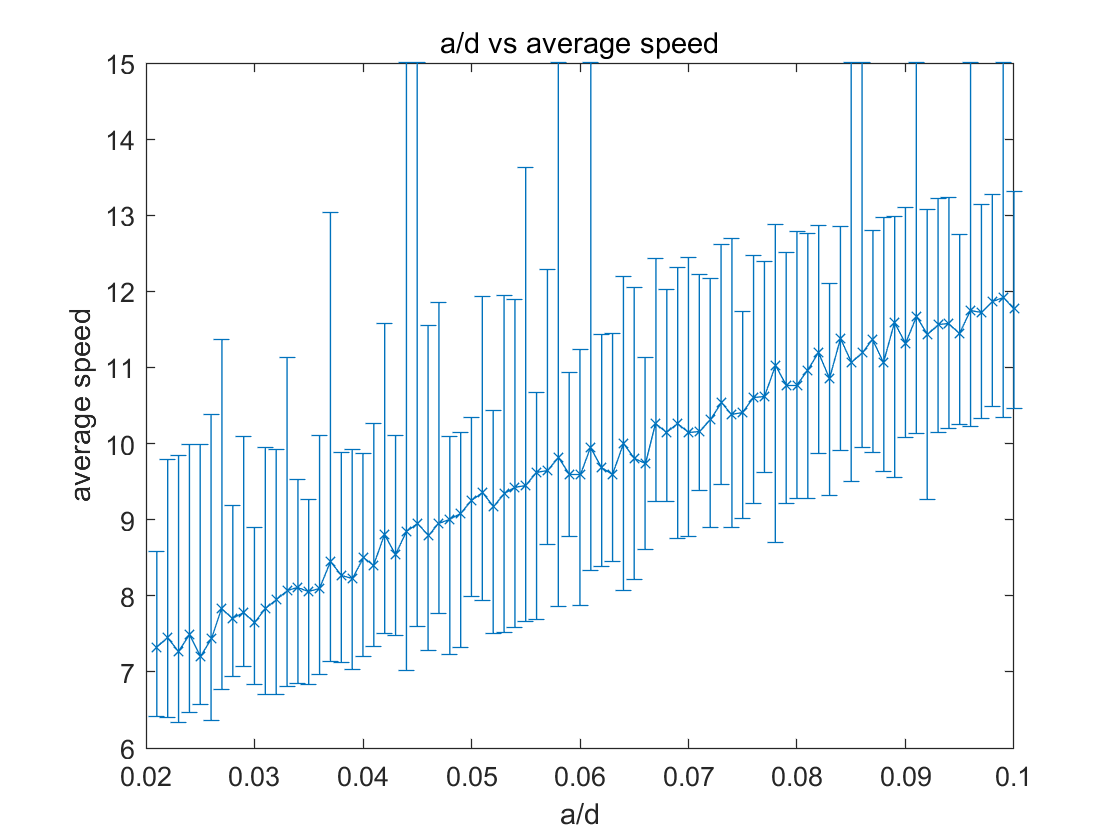


errorbar(a_d,averagespeed,minave,maxave,"-x","MarkerSize",5)
title("a/d vs average speed") 
xlabel('a/d')
ylabel('average speed')